# Deep Q-Network Agent Building for Water Tank Example

open_system("rlwatertank_discretePPO");

## Environment Definition

actInfo = rlFiniteSetSpec([0 1 2 5], Name="additional flow rate");

obsInfo = rlNumericSpec([3 1],...
    LowerLimit=[-inf -inf 0  ]',...
    UpperLimit=[ inf  inf inf]');
obsInfo.Name = "observations";
obsInfo.Description = "integrated error, error, and measured height";

env = rlSimulinkEnv("rlwatertank_discretePPO", ...
        "rlwatertank_discretePPO/RL Agent", ...
        obsInfo, actInfo);
env.ResetFcn = @(in)localResetFcn(in);

Ts = 1; % Sampling time = 1s
Tf = 200; % Max steps (s)
rng(0);

## Define the DQN Agent's Critic

Contrary to DDPG, a PPO's critic is a value function that only depends on the current state, i.e., $V(s_i)$ and returns a single scalar.

% Observation path layers
obsPath = [
    featureInputLayer(prod(obsInfo.Dimension),Name="observation")
    fullyConnectedLayer(20)
    reluLayer
    fullyConnectedLayer(10,Name="obsout")
];

% Action path layers
actPath = [
    featureInputLayer(prod(actInfo.Dimension),Name="action")
    fullyConnectedLayer(5)
    reluLayer
    fullyConnectedLayer(5,Name="actout")
];

% Common path to output layers
% Concatenate obsPath & actPath along dimension one.
comPath = [
    concatenationLayer(1,2,Name="concatenate")
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(1, Name="Q-value")
];

criticNet = dlnetwork(obsPath);
criticNet = addLayers(criticNet,actPath); 
criticNet = addLayers(criticNet,comPath);
criticNet = connectLayers(criticNet,"obsout","concatenate/in1");
criticNet = connectLayers(criticNet,"actout","concatenate/in2");

criticNet = initialize(criticNet);
summary(criticNet)

   Initialized: true

   Number of learnables: 501

   Inputs:
      1   'observation'   3 features
      2   'action'        1 features



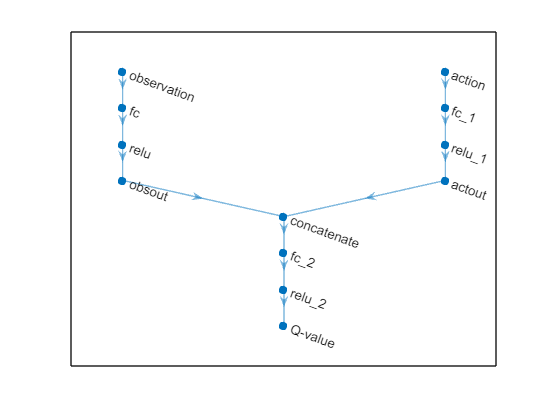


figure;
plot(criticNet);


critic = rlQValueFunction(criticNet, obsInfo, actInfo, UseDevice="gpu");

## Create the DQN Agent

agentOpts = rlDQNAgentOptions(...
    SampleTime=Ts,...
    DiscountFactor=0.99,...
    MiniBatchSize=128);
agentOpts.EpsilonGreedyExploration.Epsilon = 0.9;

agent = rlDQNAgent(critic, agentOpts);

agent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-4;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;

## Start training

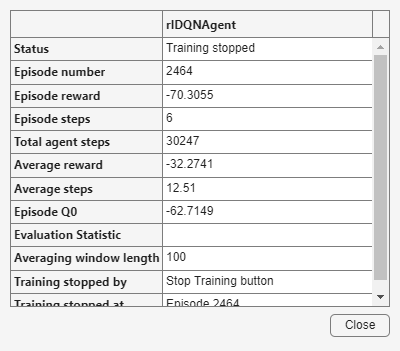

trainOpts = rlTrainingOptions(...
    MaxEpisodes=10000, ...
    MaxStepsPerEpisode=ceil(Tf/Ts), ...
    ScoreAveragingWindowLength=100, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=500);

trainingStats = train(agent, env, trainOpts);

## Validate after the training

rng(5);
simOpts = rlSimulationOptions(MaxSteps=100, StopOnError="on");
experiences = sim(env, agent, simOpts);

## Local Reset Function

function in = localResetFcn(in)
    % Randomize reference signal
    blk = sprintf("rlwatertank_discretePPO/Desired \nWater Level");
    h = 3*randn + 10;
    while h <= 0 || h >= 20
        h = 3*randn + 10;
    end
    in = setBlockParameter(in,blk,Value=num2str(h));
    
    % Randomize initial height
    h = 3*randn + 10;
    while h <= 0 || h >= 20
        h = 3*randn + 10;
    end
    blk = "rlwatertank_discretePPO/Water-Tank System/H";
    in = setBlockParameter(in,blk,InitialCondition=num2str(h));
end